Mandelbrot ref init

close all; clear; clc;

rows = 600;
cols = 800;
row_center = rows/2;
col_center = cols/2;
max_x = 6;


incr = max_x*1/2/rows

incr = 0.0050

max_iter = 20;

z0 = 0;

c_r = 0.5;
c_i = 0.5*j;
c = c_r + c_i

c = 0.5000 + 0.5000i

i = 0;
zn = z0;
zn1 = z0;
r = abs(zn1);
while(i<max_iter && r<2)
    zn = zn1;
    zn1 = zn^2 + c;
    
    r = abs(zn1);
    i = i+1;
end

i

i = 5

r

r = 3.5494

zn1

zn1 = 3.2852 + 1.3438i

mandelmap = zeros(rows,cols);
i = 0;
zn = z0;
zn1 = z0;
r = abs(zn1);
for row=0:rows
    for col=0:cols
        c_r = (col-col_center)*incr;
        c_i = j*(row-row_center)*incr;
        c = c_r + c_i;
        
        i = 0;
        zn = z0;
        zn1 = z0;
        r = abs(zn1);
        
        while(i<max_iter && r<2)
            zn = zn1;
            zn1 = zn^2 + c;
            
            r = abs(zn1);
            i = i+1;
        end
        
        if i<max_iter
            mandelmap(row+1,col+1) = i;
        else
            mandelmap(row+1,col+1) = 0;
        end
    end
end

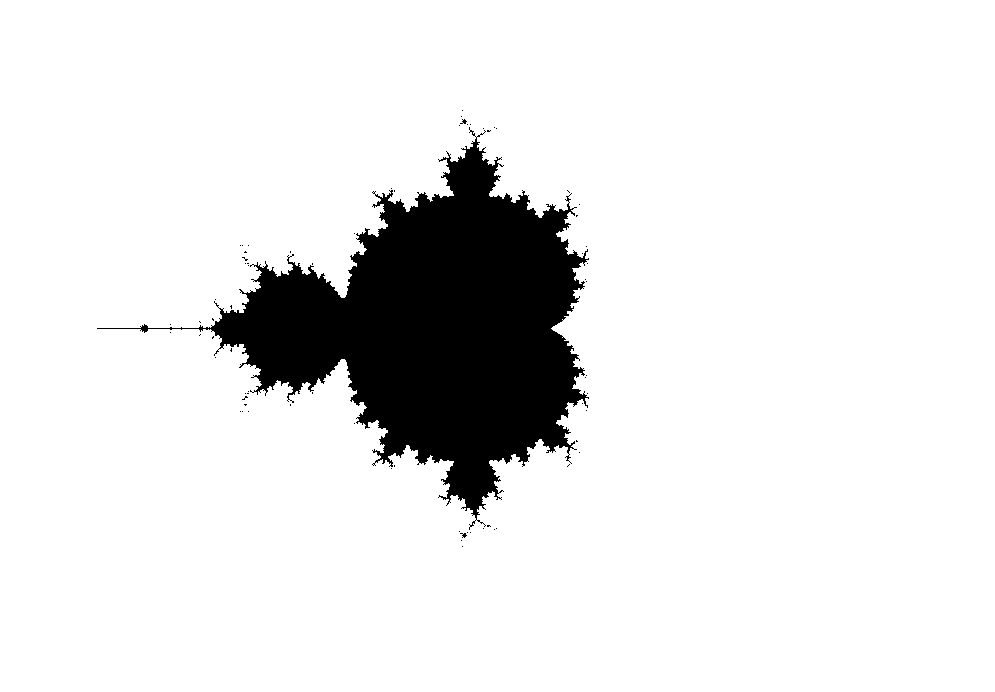

figure
imshow(mandelmap)